# 1.主轴跟踪(主轴环, 控制中包含耦合项)

clear
clc
 
ulogOBJ = ulogreader("log_19_2021-6-30-08-03-58.ulg");
msg = readTopicMsgs(ulogOBJ);

## 主轴跟踪数据

 
% 获取 known_logger 数据
logSampleRate = 20;
known_logger = msg.TopicMessages{12};
% 生成相对时间
log_time = known_logger.timestamp;
[sample_count,~] = size(log_time);
relativeTime = 0:1/logSampleRate:((sample_count-1)*(1/logSampleRate));
%
% 获取数据
h1 = known_logger.h1;
h2 = known_logger.h2;
h1d = known_logger.h1d;
h2d = known_logger.h2d;
tDes = known_logger.tdes;
iter = known_logger.iter;

% 画图
s = figure(11);
s.Position(4) = 16;
clf

## 主轴跟踪

subplot(6,1,1)
plot(relativeTime, h1)
hold on 
plot(relativeTime,h1d)
xlim([0,140])
ylabel("$h_1$","Interpreter","latex")
legend("measurement","reference",'Orientation',"horizontal","Location","northwest")

## 迭代次数

subplot(6,1,3)
plot(relativeTime,iter)
xlim([0,140])
ylim([0,10])
ylabel("iterations","Interpreter","latex")

## 电机拉力输出(推算)

subplot(6,1,6)
plot(relativeTime,tDes(:,2)/5*8.5)
xlim([0,140])
ylim([0,10])
ylabel("rotor 4(N)","Interpreter","latex")
xlabel("Time(s)")

subplot(6,1,4)
plot(relativeTime,tDes(:,3)/5*8.5)
xlim([0,140])
ylim([0,10])
ylabel("rotor 2(N)","Interpreter","latex")

subplot(6,1,5)
plot(relativeTime,tDes(:,4)/5*8.5)
xlim([0,140])
ylim([0,10])
ylabel("rotor 3(N)","Interpreter","latex")

## 增加角速率数据

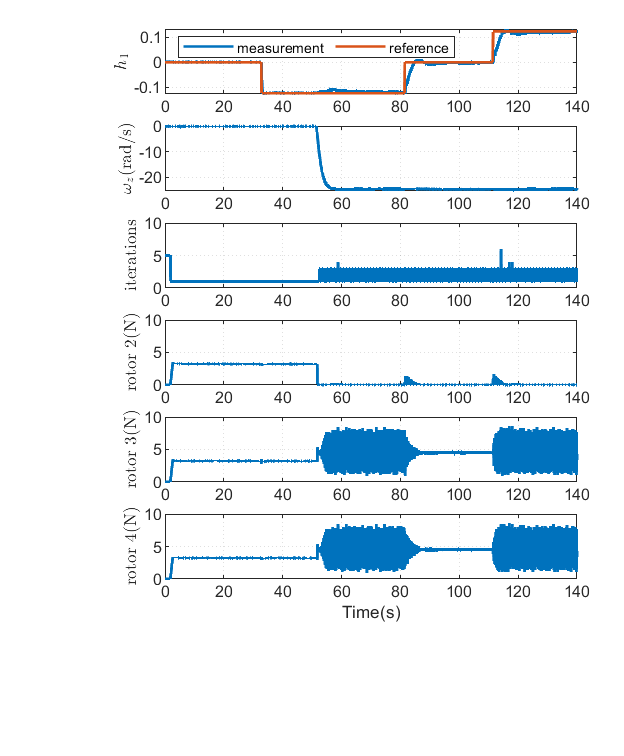

% 获取 sensor_combined 数据
logSampleRate = 200;
sensor_combined = msg.TopicMessages{21};
% 生成相对时间
log_time = sensor_combined.timestamp;
[sample_count,~] = size(log_time);
relativeTime = 0:1/logSampleRate:((sample_count-1)*(1/logSampleRate));

% 获取数据
gyro = sensor_combined.gyro_rad;
subplot(6,1,2)
plot(relativeTime, gyro(:,3))
xlim([0,140])
ylabel("$\omega_z$(rad/s)","Interpreter","latex")

# 2.角速率跟踪(主轴环前飞后飞)

clear
clc
 
ulogOBJ = ulogreader("log_1_2021-6-30-08-04-50.ulg");
msg = readTopicMsgs(ulogOBJ);

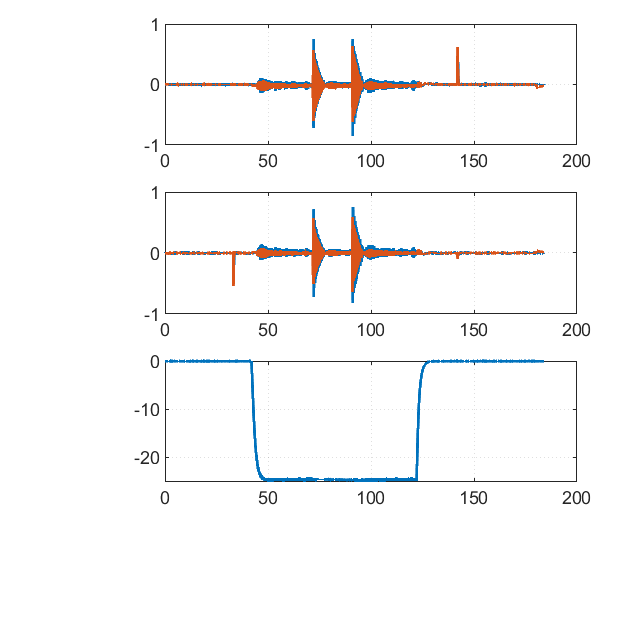

% 获取 known_logger 数据
logSampleRate = 50;
known_logger = msg.TopicMessages{12};
% 生成相对时间
log_time = known_logger.timestamp;
[sample_count,~] = size(log_time);
relativeTime = 0:1/logSampleRate:((sample_count-1)*(1/logSampleRate));

% 获取数据
pq = known_logger.pq;
pqd = known_logger.pqd;
r = known_logger.r;

% 画图
figure(21)
clf
subplot(3,1,1)
plot(relativeTime, pq(:,1))
hold on
plot(relativeTime, pqd(:,1))
% xlim([30,60])

subplot(3,1,2)
plot(relativeTime, pq(:,2))
hold on
plot(relativeTime, pqd(:,2))
% xlim([30,60])

subplot(3,1,3)
plot(relativeTime, r)

% xlim([30,130])

# 3.虚拟通道对比/欧拉角(主轴环悬停)

clear
clc
 
ulogOBJ = ulogreader("log_7_2021-6-30-08-02-38.ulg");
msg = readTopicMsgs(ulogOBJ);

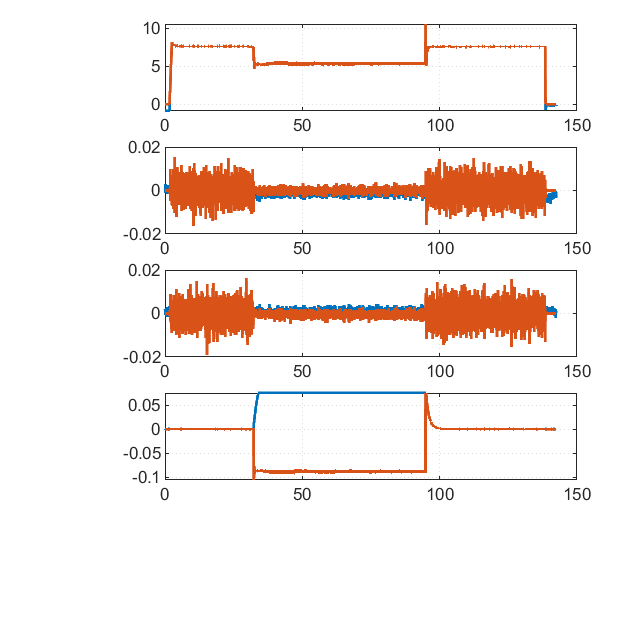

% 获取 known_logger 数据
logSampleRate = 50;
known_logger = msg.TopicMessages{12};
% 生成相对时间
log_time = known_logger.timestamp;
[sample_count,~] = size(log_time);
relativeTime = 0:1/logSampleRate:((sample_count-1)*(1/logSampleRate));

% 获取数据
chVDes = known_logger.chvdes;
tDes = known_logger.tdes;
loe = known_logger.loe;

% 选取和HIL中模型一致的控制分配矩阵参数
c = (0.0166);
l = (0.125);
% l = (0.225);
J = (diag([0.0056 0.0056 0.0104]));
% J = (diag([0.0194 0.0194 0.0291]));
M = ([ 1          1          1         1;
      -0.7071*l  -0.7071*l   0.7071*l  0.7071*l;
       0.7071*l  -0.7071*l  -0.7071*l  0.7071*l;
       c         -c          c        -c]);

% % 获取虚拟控制通道向量,即总的拉力和三个轴的力矩
% vAct = zeros(sample_count,4);
% for i = 1:sample_count
%     vAct(i,:) = M*((tDes(i,:))');
% end
% 获取实际的包含故障信息的虚拟控制通道向量
vActFault = zeros(sample_count,4);
for i = 1:sample_count
    vActFault(i,:) = M*((tDes(i,:))'.*[loe(i),1,1,1]');
end

% 画图
figure(31)
clf
subplot(4,1,1)
plot(relativeTime, chVDes(:,1))
hold on
plot(relativeTime, vActFault(:,1))

subplot(4,1,2)
plot(relativeTime, chVDes(:,2))
hold on
plot(relativeTime, vActFault(:,2))

subplot(4,1,3)
plot(relativeTime, chVDes(:,3))
hold on
plot(relativeTime, vActFault(:,3))

subplot(4,1,4)
plot(relativeTime, chVDes(:,4))
hold on
plot(relativeTime, vActFault(:,4))

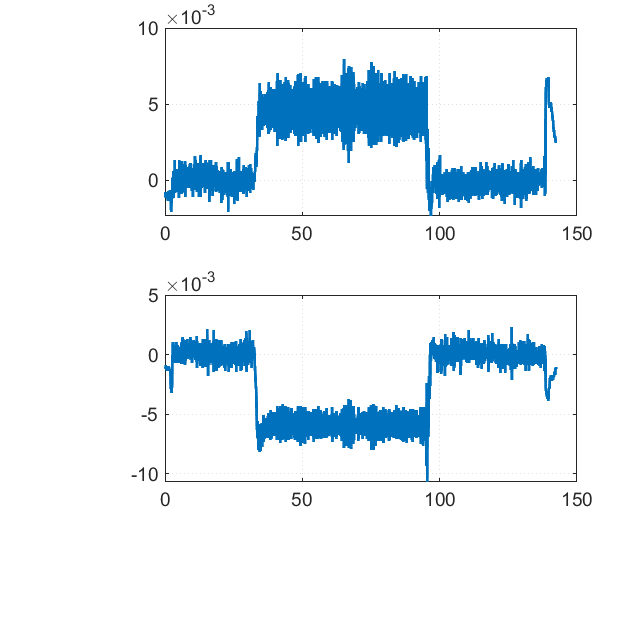

% 获取 vehicle_attitude 数据
logSampleRate = 20;
vehicle_attitude = msg.TopicMessages{35};
% 生成相对时间
log_time = vehicle_attitude.timestamp;
[sample_count,~] = size(log_time);
relativeTime = 0:1/logSampleRate:((sample_count-1)*(1/logSampleRate));

% 获取数据
quate = vehicle_attitude.q;

% 处理数据
[yaw, pitch, roll] = quat2angle(quate);

figure(32)
clf
subplot(2,1,1)
plot(relativeTime, roll)

subplot(2,1,2)
plot(relativeTime, pitch)

# 4.方位角和电机拉力的关系

clear
clc
 
ulogOBJ = ulogreader("log_20_2021-6-30-08-02-04.ulg");
msg = readTopicMsgs(ulogOBJ);

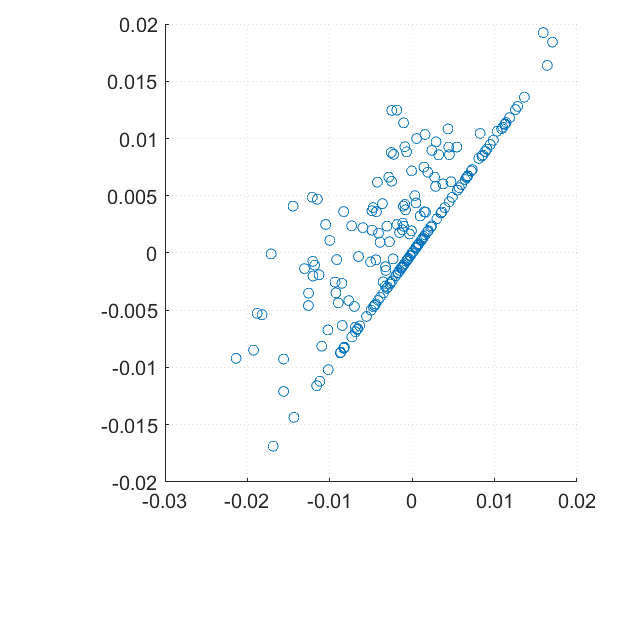

 
% 获取 known_logger 数据
logSampleRate = 20;
known_logger = msg.TopicMessages{12};
% 生成相对时间
log_time = known_logger.timestamp;
[sample_count,~] = size(log_time);
relativeTime = 0:1/logSampleRate:((sample_count-1)*(1/logSampleRate));

% 获取数据
tDes = known_logger.tdes;
psi = known_logger.psi;

% 选取和HIL中模型一致的控制分配矩阵参数
c = (0.0166);
l = (0.125);
% l = (0.225);
J = (diag([0.0056 0.0056 0.0104]));
% J = (diag([0.0194 0.0194 0.0291]));
M = ([ 1          1          1         1;
      -0.7071*l  -0.7071*l   0.7071*l  0.7071*l;
       0.7071*l  -0.7071*l  -0.7071*l  0.7071*l;
       c         -c          c        -c]);

% % 获取虚拟控制通道向量,即总的拉力和三个轴的力矩
% vAct = zeros(sample_count,4);
% for i = 1:sample_count
%     vAct(i,:) = M*((tDes(i,:))');
% end
% 获取实际的包含故障信息的虚拟控制通道向量
vActFault = zeros(sample_count,4);
for i = 1:sample_count
    vActFault(i,:) = M*((tDes(i,:))'.*[0,1,1,1]');
end

% 时间
tStart = 50;
tEnd = 60;
sampleVector = tStart*logSampleRate:tEnd*logSampleRate;

% 画图
figure(41)
% clf
% plot(relativeTime,psi)
clf
% scatter(psi(sampleVector)*180/pi,tDes(sampleVector,2))
% hold on
% scatter(psi(sampleVector)*180/pi,tDes(sampleVector,4))
scatter(vActFault(sampleVector,3),vActFault(sampleVector,2))